# **Metoda największego spadku**

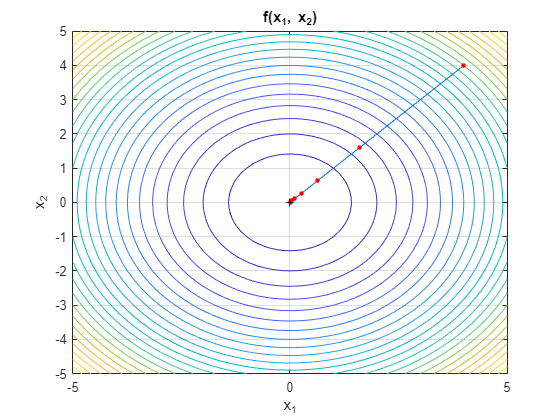

clearvars all; close all;
syms x1 x2

f1 = x1.^2 + x2.^2;
f2 = matlabFunction(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = matlabFunction(grad);
grad = @(x) G(x(1), x(2));

eps = 1e-2;
P = [4, 4];
h0 = 0.3;
max_iter = 100;

[min, iter, x] = const_steepest_descent_method(f, grad, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)

display_results(f, min, iter)

Number of iterations: 7
Point x*: 0.002621, 0.002621
Function value at x*: 0.000014


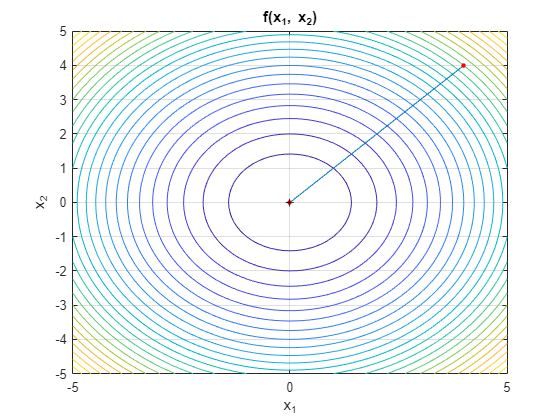


[min, iter, x] = steepest_descent_method(f, grad, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 0.000000, 0.000000
Function value at x*: 0.000000


# **Metoda Newtona**

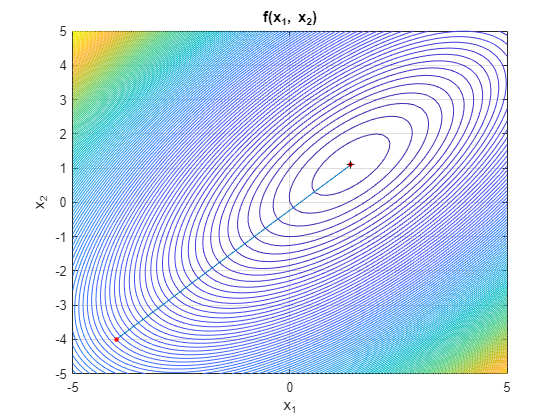

f1 = 3*x1.^2 + 3*x2.^2 - 4*x1*(1+x2) - x2 + 2;
f2 = matlabFunction(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = matlabFunction(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes = inline(hes1);

eps = 1e-2;
P = [-4, -4];
h0 = 0.05;
max_iter = 100;

[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)

display_results(f, min, iter)

Number of iterations: 1
Point x*: 1.400000, 1.100000
Function value at x*: -1.350000


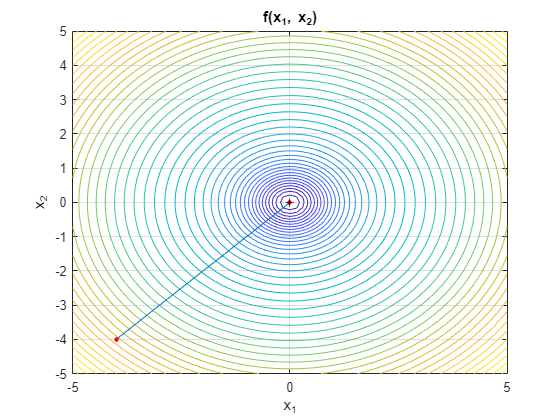


f1 = x1.^2 + x2.^2 - 40/(x1.^2 + x2.^2 + 1);
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes2 = inline(hes1);
hes = @(x) hes2(x(1), x(2));

eps = 1e-2;
P = [-4, -4];
h0 = 0.05;
max_iter = 100;

[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-5 5 -5 5], 2)

display_results(f, min, iter)

Number of iterations: 1
Point x*: -0.000063, -0.000063
Function value at x*: -40.000000


# **Porównanie metod**

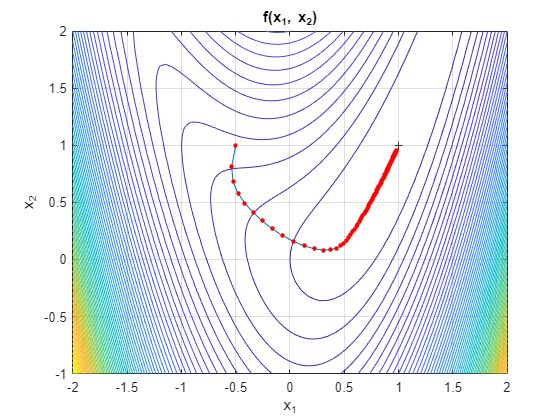

clearvars all; close all;
syms x1 x2

f1 = 2.5*(x1.^2 - x2).^2 + (1 - x1).^2;
f2 = matlabFunction(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = matlabFunction(grad);
grad = @(x) G(x(1), x(2));

eps = 1e-3;
P = [-0.5, 1];
h0 = 0.05;
max_iter = 200;

[min, iter, x] = const_steepest_descent_method(f, grad, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -1 2], 1)

display_results(f, min, iter)

Number of iterations: 148
Point x*: 0.978700, 0.954344
Function value at x*: 0.000484


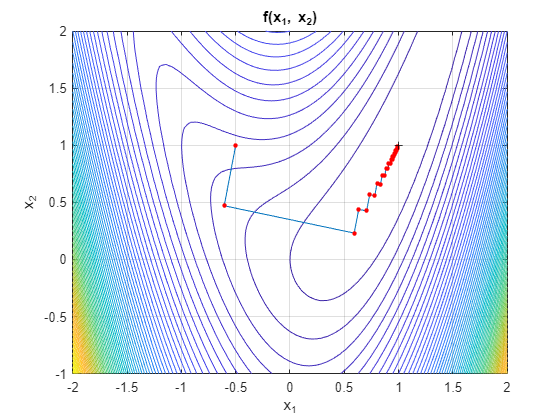


[min, iter, x] = steepest_descent_method(f, grad, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -1 2], 1)

display_results(f, min, iter)

Number of iterations: 33
Point x*: 0.994420, 0.987858
Function value at x*: 0.000034


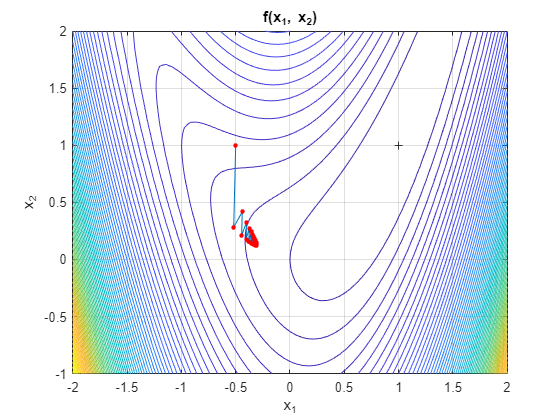


[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -1 2], 1)

display_results(f, min, iter)

Number of iterations: 104
Point x*: -0.305084, 0.131408
Function value at x*: 1.706918


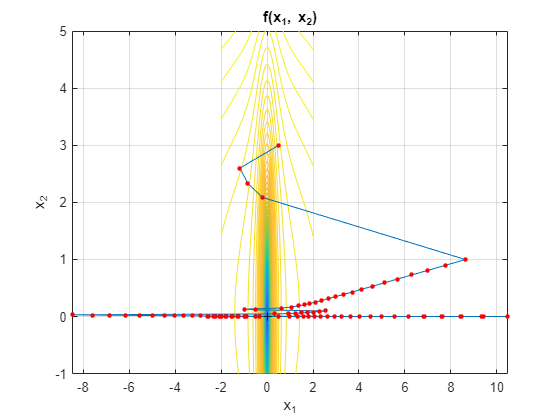

f1 = x1.^2 + x2.^2 - 400/(100*x1.^2 + x2.^2 + 1);
f2 = inline(f1);
f = @(x) f2(x(1), x(2));

grad = gradient(f1);
G = inline(grad);
grad = @(x) G(x(1), x(2));

hes1 = hessian(f1);
hes2 = inline(hes1);
hes = @(x) hes2(x(1), x(2));

eps = 1e-2;
P = [0.5, 3];
h0 = 0.05;
max_iter = 100;

[min, iter, x] = const_steepest_descent_method(f, grad, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -1 5], 5)

display_results(f, min, iter)

Number of iterations: 100
Point x*: 6.815611, 0.000008
Function value at x*: 46.366465


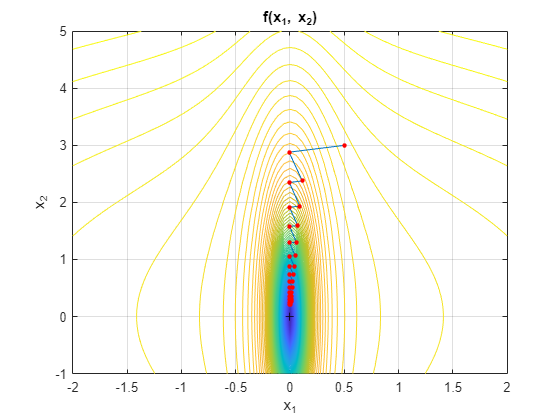


[min, iter, x] = steepest_descent_method(f, grad, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -1 5], 5)

display_results(f, min, iter)

Number of iterations: 28
Point x*: -0.000536, 0.214576
Function value at x*: -382.336996


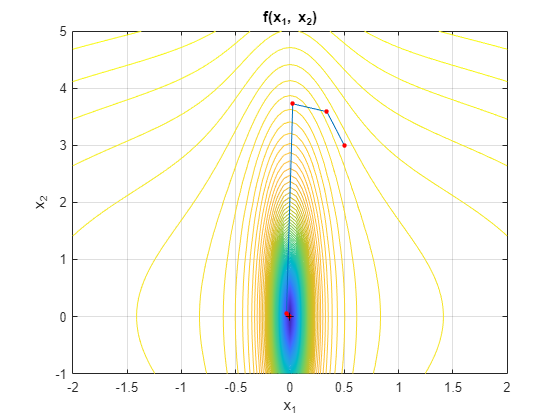


[min, iter, x] = newton_method(f, grad, hes, P, h0, eps, max_iter);
display_method(f1, f, x, [0 0], [-2 2 -1 5], 5)

display_results(f, min, iter)

Number of iterations: 4
Point x*: 0.000001, 0.000061
Function value at x*: -399.999998


function display_method(f1, f, x, xs, ax, step)
    figure()
    fcontour(f1, ax, 'LevelStep', step); grid on; hold on;
    %title({"f(x_1, x_2) = " + latex(f1)});
    
    title('f(x_1, x_2)'); xlabel('x_1'); ylabel('x_2'); 
    plot(x(:,1), x(:,2), '-', 'Marker', '.', 'MarkerSize', 10, 'MarkerEdgeColor', 'r')
    f_min = fminsearch(f,xs(1,:));
    
    plot(f_min(end,1), f_min(end,2), 'k+')
    hold off
end

function display_results(f, min, iter)
    fprintf('Number of iterations: %d\n', iter)
    fprintf('Point x*: %f, %f\n', min(:,1), min(:,2))
    fprintf('Function value at x*: %f\n', f(min))
end